## МИУ

Программа E-поляризация МИУ для цилиндра квадратного сечения

16_12_20

Входные параметры

close all;
clear variables;

Входные параметры

% global N as dx

k = 2*pi; % волновое число, при лямде = 1
as = 2; % ширина ленты
N = 400; % количество точек коллокации
phi_grad = 0; % угол падения волны [град]
dx = as/N; % растояние между центрами цилиндров

Замена переменных

Новые константы

kdx = k*dx;
gamma = 1.781072417990;
kd4 = kdx/4;
% dx2 = dx/2;
delta = dx/2;
kd6 = kdx/6;
    D0 = kdx*(1+(1i*2/pi)*(log(gamma*kd4)-1));
    D1 = kdx*(1+(1i/pi)*(3*log(3*gamma*kd4)-log(gamma*kd4)-2));
    D2 = kdx*(1+(1i*2/pi)*(log(2*gamma*kd4)-1));

Порог

treshold = 1*dx;
% str = sprintf('Будет посчитано %.f матричных элементов через формулу',  fix(treshold/dx));
% disp(str)
% 
% if treshold == dx
%     warning('Порог равен dx, один матричный элемен будет вычислен аналитически')    
% elseif treshold <= dx
%     warning('Порог меньше dx, ни одного матричного элемента не будет вычислено аналитически')    
%     str2 = sprintf('Порог были принят равным dx = %.i',  dx);
%     disp(str2)
%     treshold = dx;
% end

Генерация точек

Расчет кооодинат центров отрезков разбиения (без функции)

% генератора координат для первого участка
for n=1:N
    x1(n) = (n-0.5)*dx;
    z1(n) = 0;
    x2(n) = as;
    z2(n) = (n-0.5)*dx;
    x3(n) = (n-0.5)*dx;
    z3(n) = as;
    x4(n) = 0;
    z4(n) = (n-0.5)*dx;  
end

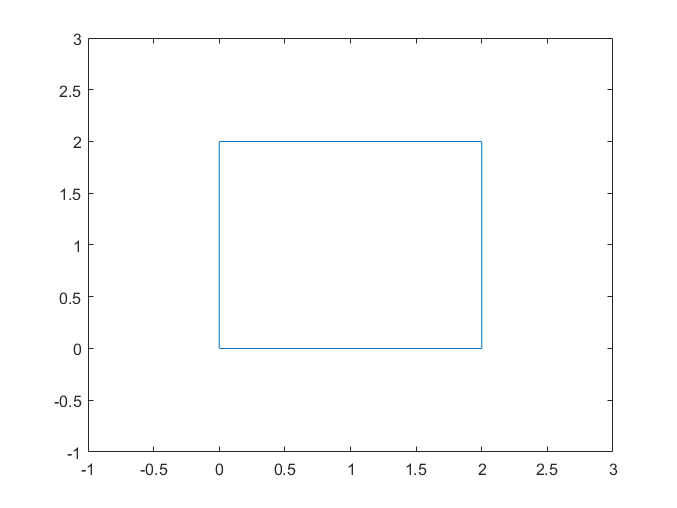

% координта на поверхности цилиндра
X = [x1 x2 fliplr(x3) x4];
Z = [z1 z2 z3 fliplr(z4)];

plot(X,Z)
xlim([-1,3])
ylim([-1,3])

Расчет касательных к отрезкам разибения

% касательные * до копирования
tx_one = [1 0 -1 0];
tz_one = [0 1 0 -1];

%  общие касательный
tz = [repmat(tz_one(1),1,N) repmat(tz_one(2),1,N) repmat(tz_one(3),1,N) repmat(tz_one(4),1,N)];
tx = [repmat(tx_one(1),1,N) repmat(tx_one(2),1,N) repmat(tx_one(3),1,N) repmat(tx_one(4),1,N)];

Посчитаем n для каждого отрезка

%   нормальный вектор найдем с помощью матрицы повороты
    a = -90;
    matrix = [cosd(a),-sind(a); sind(a),cosd(a)];

for i = 1 : 4*N
     matrix_temp = [tx(i), tz(i)]*matrix;
     nx(i) = matrix_temp(1);
     nz(i) = matrix_temp(2);
end

Изучим один цикл

count = 0;
for m = 1 : 4*N
    
%   Координаты в исходной системе координат (в ГСК) 
% - т.к. точки находятся в центре отрезков разбиения
    xm = X(m);
    zm = Z(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    
    for n = 1 : 4*N
    %   Координаты в исходной системе координат (в ГСК)
        xn = X(n);
        zn = Z(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);

    %   Центр новой системы кооридны - начало отрезка (в ГСК)

Давай возьмем середину отрезка

        x_begin_O2 = xn;
        z_begin_O2 = zn;
        
    %   Растояние между началом координат О2 и точкой наблюдений (в ГСК)
        x_mO2 = xm - x_begin_O2;
        z_mO2 =  zm - z_begin_O2;
         
%       Положим этот вектор на новую СК
%       Координаты этой точки (в ЛСК)
        xmO2 = x_mO2*txn + z_mO2*tzn;
        zmO2 = x_mO2*nxn + z_mO2*nzn;
           

Т.к. взяли на начало середину отрезка то тут будет

        xmnO2 = xmO2;
        zmnO2 = zmO2;

%       Растояние между m и n (в ГСК)
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
        
%       Расчет матричных элементов (в ЛСК)  
        if r < 0.001*dx
            Es(m,n) = D0;
   
        elseif r <= treshold
%             k_xm_plus = k*(abs(xmnO2) + delta);
%             k_xm_minus = k*(abs(xmnO2) - delta);
%             Es(m,n) = k*dx +(1i*2/pi)*( k_xm_plus*log(gamma*k_xm_plus/2)-k_xm_minus*log(gamma*k_xm_minus/2)-k*dx );
%             
            
%             Es(m,n) = k*dx+k*2*1i/pi*(dx*log(gamma*k/2)-dx*zmn*(atan(xmn_plus_delta/zmn)- atan(xmn_minus_delta/zmn)) + 0.5*xmn_plus_delta*log(r_plus_delta^2)  -  0.5*xmn_minus_delta*log(r_minus_delta^2)- dx);

            
            
            
            
%             xmn_plus_delta = (xmnO2) + delta;
%             xmn_minus_delta = (xmnO2) - delta;
%             r_plus_delta = sqrt(xmn_plus_delta^2 + zmnO2^2);
%             r_minus_delta = sqrt(xmn_minus_delta^2 + zmnO2^2);
% %             zmn = abs(zmnO2);
% %             Es(m,n) = kdx+k*2*1i/pi*(dx*log(gamma*k/2)-dx*zmn*(asin(xmn_plus_delta/r_plus_delta)- asin(xmn_minus_delta/r_minus_delta)) + 0.5*xmn_plus_delta*log(r_plus_delta^2)  -  0.5* xmn_minus_delta*log(r_minus_delta^2)- dx);
%             zmn = zmnO2;
%             Es(m,n) = kdx+k*2*1i/pi*(dx*log(gamma*k/2)-dx*zmn*(atan(xmn_plus_delta/zmn)- atan(xmn_minus_delta/zmn)) + 0.5*xmn_plus_delta*log(r_plus_delta^2)  -  0.5* xmn_minus_delta*log(r_minus_delta^2)- dx);
%             

            xmn_plus_delta = (xmnO2) + delta;
            xmn_minus_delta = (xmnO2) - delta;
            r_plus_delta = sqrt(xmn_plus_delta^2 + zmnO2^2);
            r_minus_delta = sqrt(xmn_minus_delta^2 + zmnO2^2);
            Es(m,n) = k*dx+k*2*1i/pi*(dx*log(gamma*k/2)-dx*zmn*(atan(xmn_plus_delta/zmn)- atan(xmn_minus_delta/zmn)) + 0.5*xmn_plus_delta*log(r_plus_delta^2)  -  0.5*xmn_minus_delta*log(r_minus_delta^2)- dx);

            Es(m,n) = D1;

        else
            f2 = besselh(0,1,k*r);
            Es(m,n) = k*dx*f2;
        end                    
    end
end
 

Расчет падающего поля

for m=1:4*N
    cx = -1i*k*cosd(phi_grad);
    cz = -1i*k*sind(phi_grad);
    % Определим координаты
    xm = X(m);
    zm = Z(m);
    
%   Итоговое падающее поел - это суперпозиция полей
    Ei(m,1) = +4*exp(cx*xm+cz*zm);% падающее поле X
end

Посчитаем токи и построим график

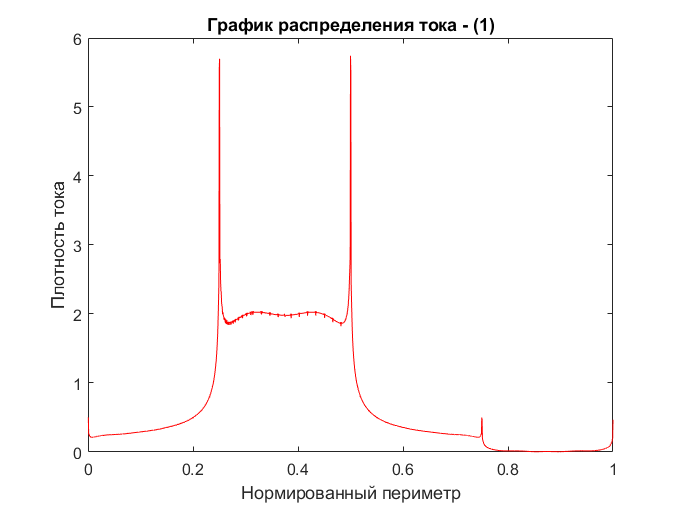

% расчеток токов ВИ 
I=Es\Ei;
       
% номера ВИ для графика 
n_for_graf = zeros(1, N);
for i = 1 : 4*N
     n_for_graf(i) = i;
end

% построение графика респределения токов в ВИ

% ось X в относительных единицах
figure;
plot(n_for_graf/(4*N), abs(I), 'r');
title('График распределения тока - (1)'); 
xlabel('Нормированный периметр'); 
ylabel('Плотность тока');

Реальный токи

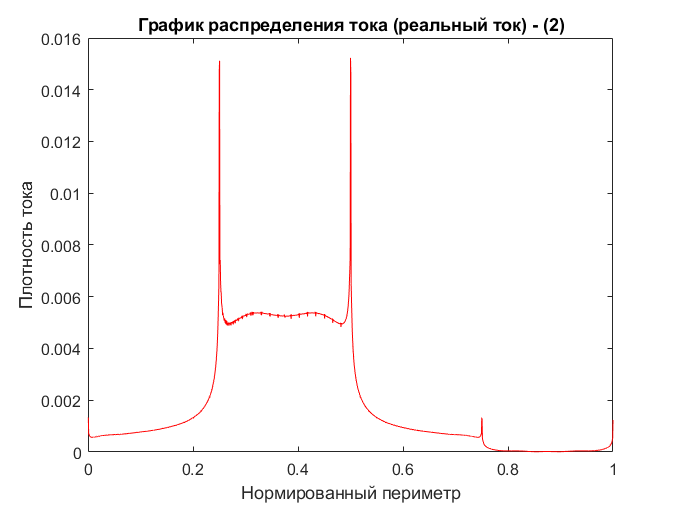

% учтем коэф мю0 который му опустили в расчетах - чтоб получить плотность тока к мА

% реальный ток в мА
I_real = I/(120*pi);

figure;
plot(n_for_graf/(4*N), abs(I_real), 'r');
title('График распределения тока (реальный ток) - (2)'); 
xlabel('Нормированный периметр'); 
ylabel('Плотность тока');

Отнормируем ось Y 

для статьи - Analysis of the Electromagnetic Scattering by Perfectly Conducting Convex Polygonal Cylinders

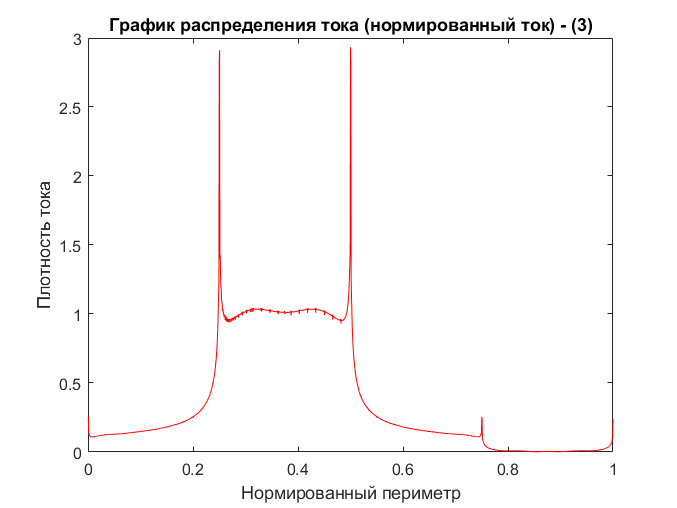

% за максимум Y примем значения в центре передней стороны падения
max_I = abs(I_real(3*N/2));

figure;
plot(n_for_graf/(4*N), abs(I_real)/max_I, 'r');
title('График распределения тока (нормированный ток) - (3)'); 
xlabel('Нормированный периметр'); 
ylabel('Плотность тока');

Ось X в длине стороны

(Токи около двойки)

для статьи - A HYBRID MULTIPOLAR-EXPANSION MOMENT-METHOD APPROACH FOR ELECTROMAGNETIC SCATTERING PROBLEMS

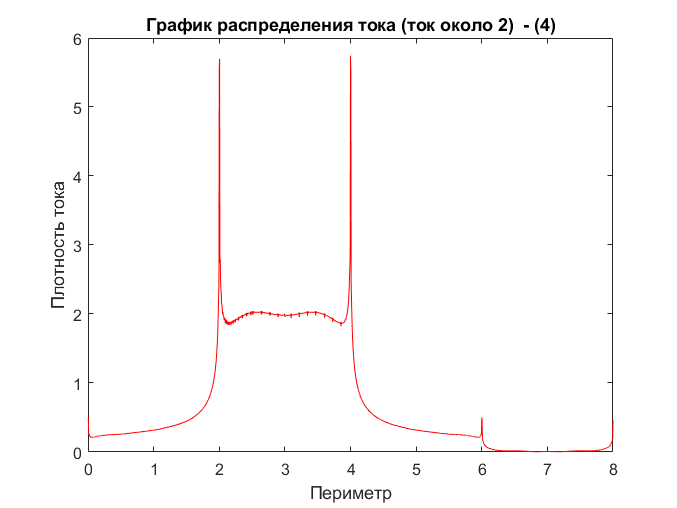

% ось X в относительных единицах
figure;
plot(n_for_graf*dx, abs(I), 'r');
title('График распределения тока (ток около 2)  - (4)'); 
xlabel('Периметр'); 
ylabel('Плотность тока');

Запись в файл токов

f01 = fopen('I_MIE_Epol_sqr_1pi.dat','w');

for n=1:4*N
    fprintf(f01,' %10.5f %10.5f\n', n_for_graf(n)/(4*N), abs(I_real(n))/max_I);
end

fclose(f01);

## ЭПР

for p = 1 : 721
    Sum_E = 0;
    phi = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
    phi_for_graf_DA(p) = (p-1)/2; % угол для графика
    
    cx = - 1i*k*cosd(phi);
    cz = - 1i*k*sind(phi);
    

        for n = 1 : 4*N
            txn = tx(n);
            tzn = tz(n);
            xn = X(n);
            zn = Z(n);
            
            Sum_E = Sum_E + k*(120*pi)/4*dx*I_real(n)*exp(cx*xn+cz*zn);      
        end
    
RCS(p) = 10*log10((2/pi)*Sum_E*conj(Sum_E));

end

% график поля в дальней зоне от угла налюденя (не нормированный)
figure;
plot(phi_for_graf_DA ,RCS,'r-');

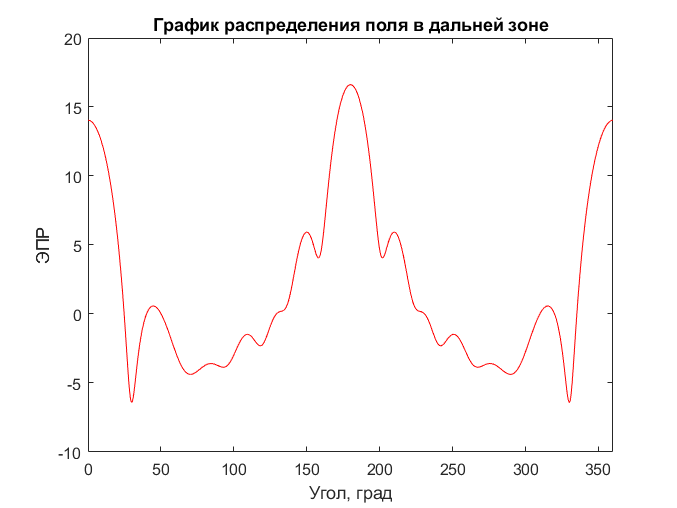

title('График распределения поля в дальней зоне'); 
xlim([0 360])
xlabel('Угол, град'); 
ylabel('ЭПР');

Запись в файл ЭПР

% f02 = fopen('DA_MIE_Epol_sqr.dat','w');
% for p = 1 : 721
%     fprintf(f02, ' %10.5f %10.5f\n', phi_for_graf_DA(p), RCS(p));
% end
% fclose(f02);